UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

2025

# *Laboratory 7: Interpolation*

## Instructions:

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name **Lab7_name_lastname.zip. **

- Send the report and all created files in a rar or zip file with name **Lab7_name_lastname.rar **and subject **Analisis_Lab7_name.** 

- You are allowed to use internet, notes, and .m files that you have created before. 

## Purposes:

- To understand the interpolation and polynomial approximation methods.

- To apply the interpolation and polynomial approximation methods.

- To implement the Langrage and Newton polynomials in Matlab.

- To interpret the Taylor polynomial approximation.

## Practice

## *Implementing*

## **Exercise 1**

- **(0.5 points)** Create a Matlab function called my_LagrangePolynomial_name_lastname() to find the coefficients of the Lagrange interpolation polynomial P(x). Remember the formulas 

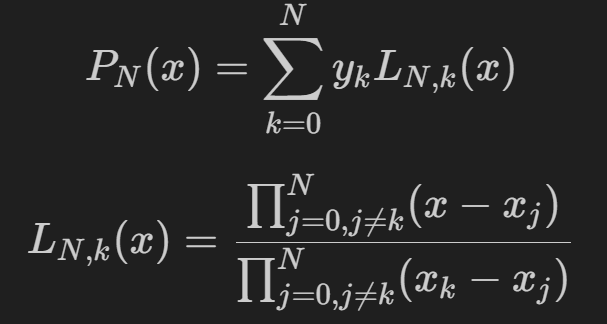 

- The function arguments must be the set of points (X, Y). Finally, evaluate the polynomial obtained at X=1.5.

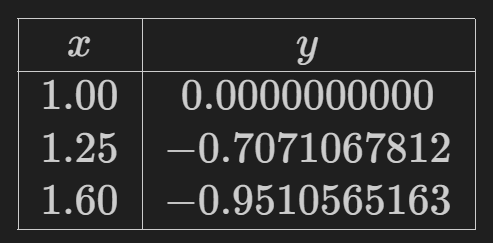

X = [1.00 1.25 1.60];
Y = [0.0 -0.7071067812 -0.9510565163];

[P] = my_LagrangePolynomial_alvaro_martinez(X, Y);

disp('Polinomio de Lagrange:')

Polinomio de Lagrange:


disp(P)

$$\frac{41996052934492105\,x^{2}}{11821949021847552}-\frac{170571520512004909\,x}{15762598695796736}+\frac{343730349798046307}{47287796087390208}$$


% Evaluar en x = 1.5
x_val = 1.5;
syms x   % <-- agrega esta línea
y_val = double(subs(P, x, x_val));

fprintf('Valor del polinomio en x = %.2f es %.6f\n', x_val, y_val);

Valor del polinomio en x = 1.50 es -0.970166


- **(0.5 points)** Using P(x) from the previous point, create a graph in the interval [0,3] and compare it with the graph of the function $\sin \left(\pi *x\right)$ in the same plot.

% Intervalo [0, 3]
x_vals = linspace(0, 3, 200);

% Evaluar el polinomio de Lagrange obtenido antes
syms x
y_poly = double(subs(P, x, x_vals));

% Evaluar la función sin(pi*x)
y_sin = sin(pi * x_vals);

% Graficar ambos
figure;
plot(x_vals, y_poly, 'r-', 'LineWidth', 2); hold on;
plot(x_vals, y_sin, 'b--', 'LineWidth', 2);
scatter(X, Y, 60, 'k', 'filled'); % puntos originales

% Personalización del gráfico
xlabel('x');
ylabel('y');
title('Comparación entre P(x) y sin(\pi x)');
legend('Polinomio de Lagrange P(x)', 'sin(\pi x)', 'Puntos originales', 'Location', 'best');
grid on;

## **Exercise 2**

- **(0.5 points)** Create a Matlab function called *my_NewtonPolynomial_name_lastname()* to find the coefficients of the Newton interpolating polynomial P1(X). Remember the formulas: 

 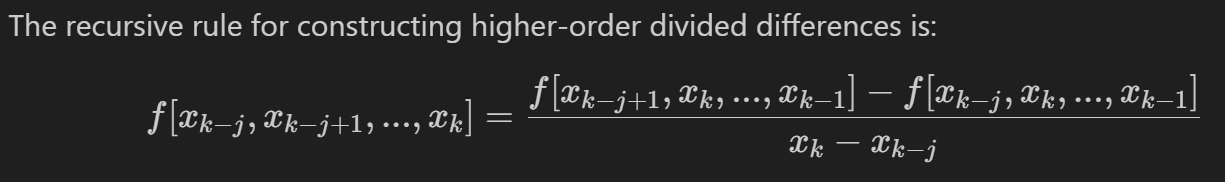

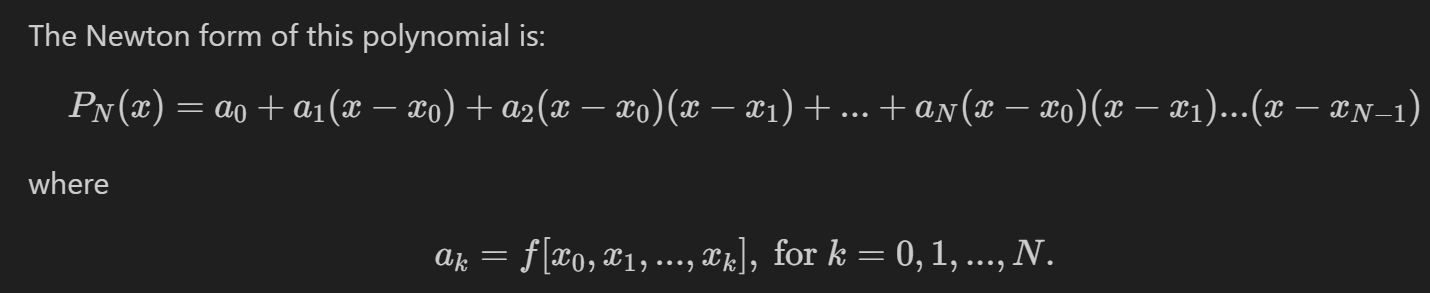

- The function arguments must be the set of points (X, Y) mentioned in the code box. Finally, evaluate the polynomial obtained at X=4.

x1 = [1, 2, 3, 4, 5, 6];
y1 = [-3, 0, 15, 48, 105, 192];

[P1] = my_NewtonPolynomial_alvaro_martinez(x1, y1);

disp('Polinomio de Newton:')

Polinomio de Newton:


disp(P1)

$$x^{3}-4\,x$$


% Evaluar el polinomio en x = 4
x_val = 4;
syms x
Evaluacion_En_X2 = double(subs(P1, x, x_val));

fprintf('El valor del polinomio en x = %.1f es %.6f\n', x_val, Evaluacion_En_X2);

El valor del polinomio en x = 4.0 es 48.000000


- **(0.5 points)** Using P(x) from the previous point, create a graph in the interval [0,3] and compare it with the graph of the function $\left(e^x \right)*0\ldotp 7$ in the same plot.

nit = 0:0.01:3;

% Evaluar la función e^x * 0.7
y_exp = (exp(nit)) * 0.7;

% Evaluar el polinomio P1 obtenido en el ejercicio anterior
syms x
y_poly = double(subs(P1, x, nit));

% Graficar ambas curvas
figure;
plot(nit, y_exp, 'b--', 'LineWidth', 2); hold on;
plot(nit, y_poly, 'r-', 'LineWidth', 2);
scatter(x1, y1, 60, 'k', 'filled'); % puntos originales

% Personalización del gráfico
xlabel('x');
ylabel('y');
title('Comparación entre P1(x) y 0.7*e^{x}');
legend('0.7 * e^{x}', 'Polinomio de Newton P1(x)', 'Puntos originales', 'Location', 'best');
grid on;
hold off;

## **Exercise 3**

- **(1.5 points) **Use the created functions for Lagrange and Newton polynomial to find each interpolating polynomial based on $f\left(x\right)=3\sin^2 \left(\frac{\pi x}{6}\right)$with$x_0 =0,x_1 =1,x_2 =2,x_3 =3$and $x_4 =4\ldotp$

- In the same plot, compare Lagrange and Newton interpolating polynomials regarding to the real function $f\left(x\right)=3\sin^2 \left(\frac{\pi x}{6}\right)$. Also, illustrate the given points $\left(x_k ,y_k \right)$. 

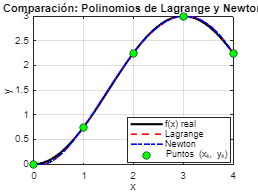

clc; clear; close all;

% Función dada
f = @(x) 3 * (sin(pi * x / 6)).^2;

% Puntos dados
X = [0 1 2 3 4];
Y = f(X);

% --- Polinomio de Lagrange ---
P_L = my_LagrangePolynomial_alvaro_martinez(X, Y);

% --- Polinomio de Newton ---
P_N = my_NewtonPolynomial_alvaro_martinez(X, Y);

% --- Evaluación numérica para graficar ---
xx = linspace(0, 4, 200);
yy_real = f(xx);
yy_L = double(subs(P_L, xx));
yy_N = double(subs(P_N, xx));

% --- Gráfica comparativa ---
figure;
plot(xx, yy_real, 'k-', 'LineWidth', 2); hold on;
plot(xx, yy_L, 'r--', 'LineWidth', 1.5);
plot(xx, yy_N, 'b-.', 'LineWidth', 1.5);
plot(X, Y, 'ko', 'MarkerFaceColor', 'g', 'MarkerSize', 7);
legend('f(x) real', 'Lagrange', 'Newton', 'Puntos (x_k, y_k)', 'Location', 'best');
xlabel('x');
ylabel('y');
title('Comparación: Polinomios de Lagrange y Newton');
grid on;


% --- Mostrar los polinomios en consola ---
disp('---------------------------------------')

---------------------------------------


disp('Polinomio de Lagrange:')

Polinomio de Lagrange:


pretty(P_L)

 4      3       2
x    7 x    47 x    5 x
-- - ---- + ----- - ---
32    16      32     16



disp('---------------------------------------')

---------------------------------------


disp('Polinomio de Newton:')

Polinomio de Newton:


pretty(P_N)

 4      3       2
x    7 x    47 x    5 x
-- - ---- + ----- - ---
32    16      32     16



disp('---------------------------------------')

---------------------------------------


## *Interpreting*

- **(1 points)** Determine the degree of the Taylor polynomial $P_N \left(x\right)$ expanded about $x_0 =\pi$ that should be used to approximate $\cos \left(\frac{33\pi }{32}\right)$ so that the error is less than ${10}^{-6}$. *Hint*. The error term $E_N \left(x\right)$ in Taylor polynomials is given by


$$E_N \left(x\right)=\frac{f^{\left(N+1\right)} \left(c\right)}{\left(N+1\right)!}{\left(X-X_0 \right)}^{\left(N+1\right)} ,$$


for some value $c=c\left(x\right)$ that lies netween $x$ and $x_0 \ldotp$

*------------------------ Write your answer here ------------------------*

El término del error es:

|$E_N \left(x\right)$| ≤ ${|x-\pi |}^{\left(N+1\right)}$/ (N-1)!

con x = 33$\pi$/32 , se tiene $|x-\pi$| = $\pi$/32

Buscamos N  tal que ${\left(\pi /32\right)}^{\left(N+1\right)}$/(N-1)! <  ${10}^{-6}$

Al evaluar, se obtiene ue para N = 4 el error ≈ 7.6×${10}^{-8}$ < ${10}^{-6}$

Por lo tanto, el polinomio de Taylor debe ser de grado 4.

*---------------------------------------------------------------------------------*

- **(0.5 points) **Explain the reasoning behind your solution to the previous problem.

*------------------------ Write your answer here ------------------------*

Se usó la fórmula del error del polinomio de Taylor: 

|$E_N \left(x\right)$| ≤ ${|x-\pi |}^{\left(N+1\right)}$/ (N-1)!

y como las derivadas de cos (x)\cos(x)cos(x) están acotadas por 1, se reemplazó $|x-\pi |$ = $\pi$/32

Luego, se probó el valor de NNN hasta que el error fuera menor que ${10}^{-6}$

El primer valor que cumple esta condición es N = 4, por lo tanto ese es el grado mínimo necesario.

*---------------------------------------------------------------------------------*